**Diseño de filtros**

En esta parte se desarrollará el diseño de filtros digitales, especialmente el enfoque está en como se puede determinar la frecuencia de corte del filtro.

Inicialmente se cargarán los datos del sensro tanto estático como en movimiento.

S = readmatrix('static.csv');
M = readmatrix('motion.csv');

Para simplificar la explicación se trabajará con 2 de los 6 canales del sensor:

- Acelerómetro en eje Z

- Giróscopo en eje X

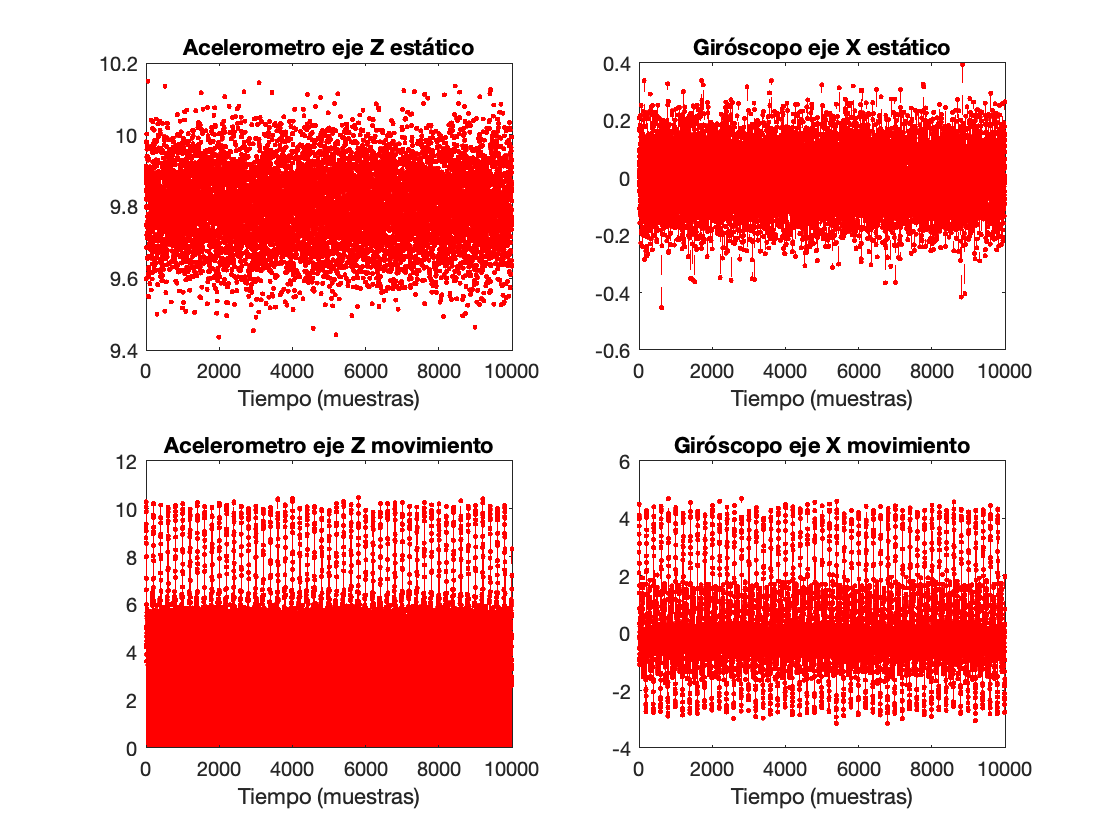

n = 0:length(S(:,3))-1;
figure()
subplot(2,2,1)
plot(n,S(:,3),'r.')
title('Acelerometro eje Z estático')
xlabel('Tiempo (muestras)')
subplot(2,2,2)
stem(n,S(:,4),'--.r')
title('Giróscopo eje X estático')
xlabel('Tiempo (muestras)')
subplot(2,2,3)
stem(n,M(:,3),'--.r')
title('Acelerometro eje Z movimiento')
xlabel('Tiempo (muestras)')
subplot(2,2,4)
stem(n,M(:,4),'--.r')
title('Giróscopo eje X movimiento')
xlabel('Tiempo (muestras)')

Los análisis que se realizarán son extrapolables a los otros canales.

Se iniciará por observar los espectros de frecuencia como se hizo en los programas anteriores. Para esta oportunidad se eliminará el componete DC de los espectros para visualizar mejor los posibles armónicos.

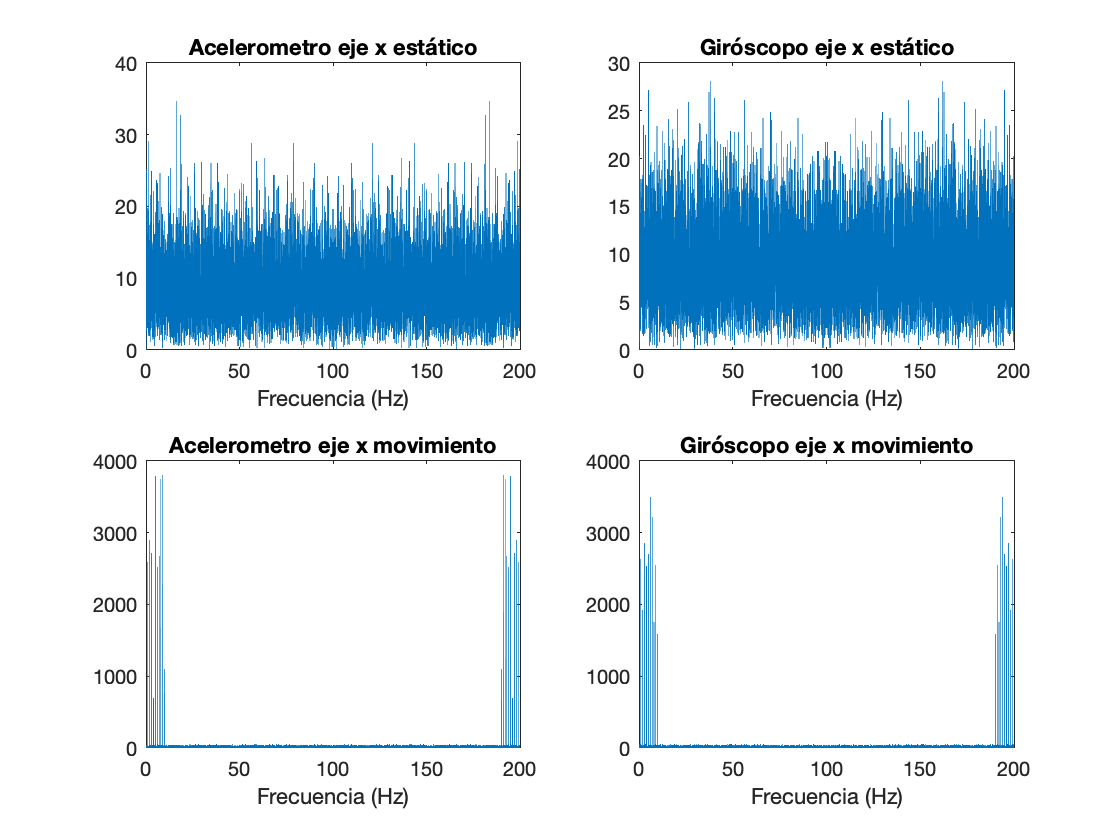

FsAc_z = abs(fft(S(:,3)));
FsAc_z(1) = 0;
FsGy_x = abs(fft(S(:,4)));
FsGy_x(1) = 0;

FmAc_z = abs(fft(M(:,3)));
FmAc_z(1) = 0;
FmGy_x = abs(fft(M(:,4)));
FmGy_x(1) = 0;

fr = n*200/length(FsAc_z);
figure()
subplot(2,2,1)
plot(fr,FsAc_z)
title('Acelerometro eje x estático')
xlabel('Frecuencia (Hz)')
subplot(2,2,2)
plot(fr,FsGy_x)
title('Giróscopo eje x estático')
xlabel('Frecuencia (Hz)')
subplot(2,2,3)
plot(fr,FmAc_z)
title('Acelerometro eje x movimiento')
xlabel('Frecuencia (Hz)')
subplot(2,2,4)
plot(fr,FmGy_x)
title('Giróscopo eje x movimiento')
xlabel('Frecuencia (Hz)')

En esta oportunidad es posible contrastar las diferencias. 

- El orden de magnitud de las amplitudes de los componetes frecuenciales. En las señales estáticas llegan alrededor de 30 o 40. Para las señales con movimiento estas alturas pueden estar cerca de 4000. Esto indica que la señal de interés posee una amplitud mucho mayor que la amplitud del ruido. Esto se conoce como SNR Signal to Noise Ratio.

- Se nota una clara diferencia en el ancho de banda que cubre la señal con movimiento. Se puede ver que va desde cerca de los 0Hz hasta 10 Hz. Mientras que el ruido cubre todo el espectro.

Las condiciones mencionadas conforman un escenario favorable para la aplicación de filtros convencionales (FIR y/o IIR). A continuación se realizará la simulación del la aplicaciónde un filtro FIR

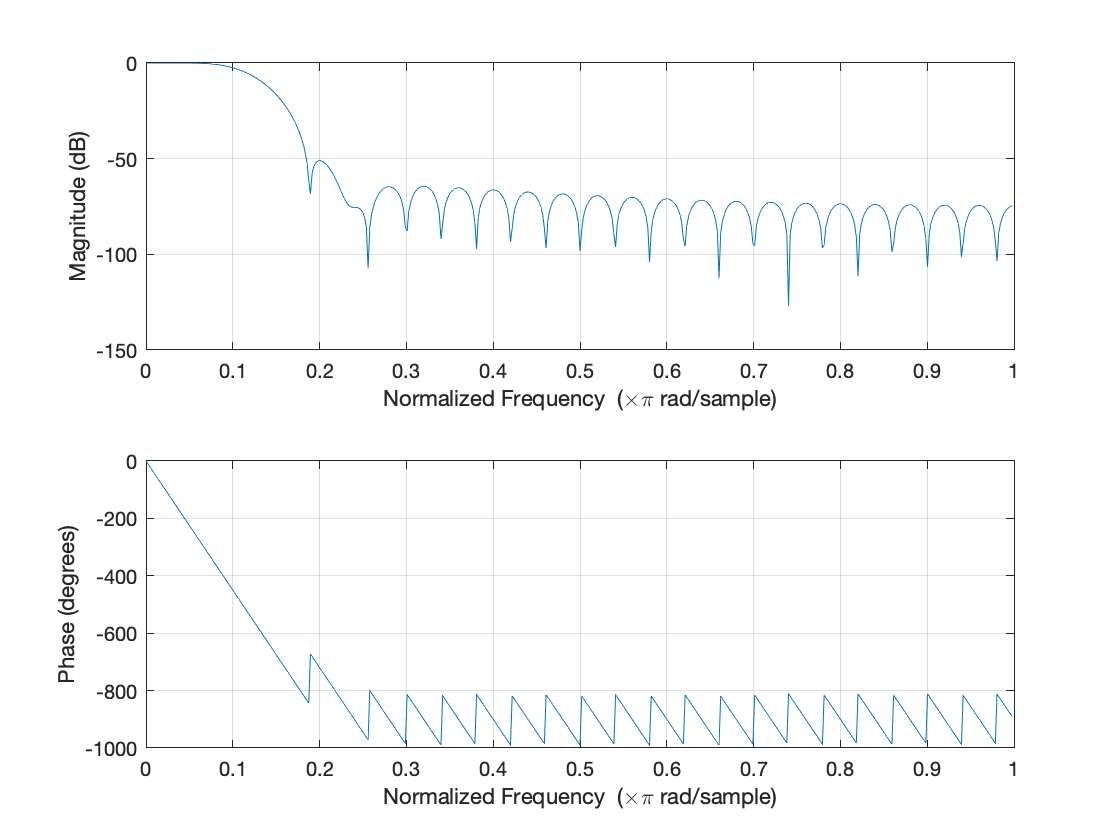

%Filtro FIR por enventanado
Fs = 200; %muestras/segundo
Fc = 12; %ciclos/segundo
fc = 2*(Fc/Fs); %Pi rad/muestra
hn = fir1(50,fc);
figure()
freqz(hn,1)


%filtrando señales estáticas
Acf_z = filter(hn,1,S(:,3));
Gyf_x = filter(hn,1,S(:,4));
